## **Why use computational modelling in infant (or developmental) research?**

Understanding how infants learn, not just what they do, is central to developmental science. Traditional tools like observational experiments have  taken the field a long way in describing what changes aceoss development. 

Computational modeling adds a complementary tool to this toolkit: rather than  only asking whether behavior differs between groups or ages, it lets researchers  test explicit, formal hypotheses about the internal variables: beliefs, learning rates, memory representations, that are thought to give rise to the behavioural patterns in the first place.

In this primer, we apply that same logic to volatility learning: rather than  asking only whether infants adapt to changing environments, we use computational modelling to ask how, estimating the specific belief-updating processes that explain their anticipatory looking behaviour, trial by trial.

## **What data can we model?**

In principle, any observable behaviour can be modelled. Here, we are interested in how infants adapt their looking behaviour in anticipation of a potential  reward. When we model this, we estimate the latent parameters that govern this behaviour to explain why some infants are better at adapting to change and learning in volatile tasks compared to others.

In this tutorial, we will be using trialwise anticipatory looking behaviour, coded in a binary fashion. The coding is arbitrary: here, we use "1" to mean the infant's very first anticipatory look during a predetermined window was to the left, and "0" to mean that it was to the right. 

The outcome, or the reward sequence, is coded in the same binary fashion: "1" means the reward (animation) was presented in the left cued location, and "0"  that it was presented in the right cued location. 

The model we use also allows for modelling of not just categorical/binary data, but continuous data as well: for example, latency of first anticipatory saccade.

## **Getting started with computational modelling in Matlab**

This tutorial uses the **HGF Toolbox**, part of **TAPAS** ([translationalneuromodeling/tapas](https://github.com/translationalneuromodeling/tapas)), an open-source suite of tools developed for computational modelling of behaviour and physiology, widely used across computational psychiatry and neuroscience. Below is a step-by-step overview to help you get started, even if you're new to computational modelling.

**1. Install TAPAS**

Download or clone the TAPAS repository, and add it (along with its subfolders) to your MATLAB path:

addpath(genpath('/path/to/tapas'));

**2. Understand the three pieces of an HGF model**

Before fitting anything, it helps to know that every HGF model is built from three components:

- **A perceptual model: **describes how beliefs are updated over time, given a sequence of inputs (in our case, an infant's trial-by-trial experience of which side shows the reward). This is the HGF itself.

- **A response model: **describes how the underlying beliefs translate into observable behavior (in our case, anticipatory looks).

- **An optimization algorithm: **the method used to find the parameter values that best explain the observed behavior, given the two models above.

You don't need to build any of these from scratch as TAPAS provides ready-made functions for each.

**3. Prepare your data**

Your data needs two key ingredients for each infant:

- `u`: the input sequence: what actually happened on each trial (e.g., which side the target appeared on)

- `y`: the observed responses: what the infant did on each trial (e.g., their anticipatory look, coded numerically)

Here, we use the data from the ZoekHetMonstertje probabilistic reversal learning task. For each infant, we have data from maximum 70 trials, coded in the above binary fashion. Missing trials (i.e. trials on which the infant did not pay attention or gaze behaviour was not acquired) are coded as NaN. We refer to the sequence of anticipatory looks as "choice" data, and to the reward sequence as "input". Both data should be in separate .txt files, without any column  headers, and comprise a single column. 

We will use the example files "input.txt" and "subID079_choice.txt" for the  modelling. These represent the real input on the probabilistic reversal task, and the real anticipatory looking data of one example infant.

First, we will load the data.

u = load('input.txt'); 
y = load('subID079_choice.txt');

**4. Fit the model**

The core function you'll use is `tapas_fitModel`, which takes the infant's responses, the inputs, and your chosen perceptual and response models, and returns a fitted model containing each participant's estimated parameters:

Here, we use the "ehgf_binary" perceptual model and the "softmax_binary" model.

est = tapas_fitModel(y, ...
    u, ...
    'tapas_ehgf_binary_config', ...   % perceptual model
    'tapas_softmax_binary_config', ...   % response model
    'tapas_quasinewton_optim_config'); % optimization algorithm

In the default configuration from TAPAS, this model assumes that infants track whether and how often changes to the reward schedule occur, and so in a hierarchical fashion. Two parameters are typically estimated in the full three-level HGF: ω2 and ω3, with ω2 representing tonic volatility (how readily beliefs at the value level update in response to new information) and ω3 representing meta-volatility, or how much the environment's volatility is itself expected to change over time.

We fit (i.e. estimate for each infant) only ω2, fixing ω3 to its default value, since these two parameters trade off against one another and are difficult to estimate reliably together, especially with the limited trial numbers typical of infant studies. Fixing ω3 allows ω2, which is our primary parameter of interest, to be estimated with much greater precision and stability.

To determine yourself which parameters you'd like to fit (i.e. estimate) and which you'd like to fix (meaning that each infant would have the same value of this parameter), you can do in the following fashion:

my_perceptual_model_config = tapas_ehgf_binary_config();
my_perceptual_model_config.omsa(1,3) = 0;
my_perceptual_model_config.omsa(1,2) = 6;

Here, we create a version of the tapas_ehgf_binary_config, and then fix the variance of ω3 to 0 (which essentially fixes it to it default value). We set the variance of ω2 to 6 to allow for sufficient individual variation.

You can check the default variance or prior mean of your parameters:

my_perceptual_model_config.ommu(1,2)

The default prior mean of ω2 is -3. If you have a reason to believe you need to change it (for example, your task is more stable, which would require a lower tonic volatility), you can also do so:

my_perceptual_model_config.ommu(1,2) = -6;

The same can be done about the response model softmax_binary. Here, we use the default configuration (prior mean=48, variance=1) that assumes that infants generally stick to their predictions.

Fit your custom model like this:

my_perceptual_model_config = tapas_ehgf_binary_config();
my_perceptual_model_config.omsa(1,3) = 0;
my_perceptual_model_config.omsa(1,2) = 6;

est = tapas_fitModel(y, ...
    u, ...
    my_perceptual_model_config, ...   % perceptual model
    'tapas_softmax_binary_config', ...   % response model
    'tapas_quasinewton_optim_config'); % optimization algorithm

**5. Inspect and extract your parameters**

Once fit, we see that the model estimates that infant with subID 079 has an ω2 of -0.3791 (while ω3 matches our fixed value of 2). We can extract the specific ω2 value:

omega2 = est.p_prc.om(2); 

We can also extract the model's estimate about the trajectory of the infant's predictions and updates about where the target would be on each trial:

muhat1 = est.traj.muhat(:,1);

We can plot these trajectories to visualise how the infant is making predictions, reflected in their anticipatory looks:

tapas_hgf_binary_plotTraj(est) 

The top level of the figure visualises the infant's beliefs about meta-volatility (how often the reward associations change). Because our task is quite volatile, this trajectory is more or less stable, but you can see the peaks when a reversal occurs (e.g. on trials 16, 26, and so on).

The middle level denotes the infant's beliefs about the tendency of reward likelihoods to change. As you can see, it follows the reinforcement schedule quite well.

Finally, the bottom panel depicts two things: in red, the model's estimate of the infant's predictions about which side the reward will appear on, and in black: their learning rate. The input (the reward sequence) is in green, the infant's response is in yellow, and yellow X denote the trials on which no gaze data was available. As missing data is quite often found in infant studies, it is good to see that the model converges and provides a reasonable fit or an infant with about 17% missing trials.

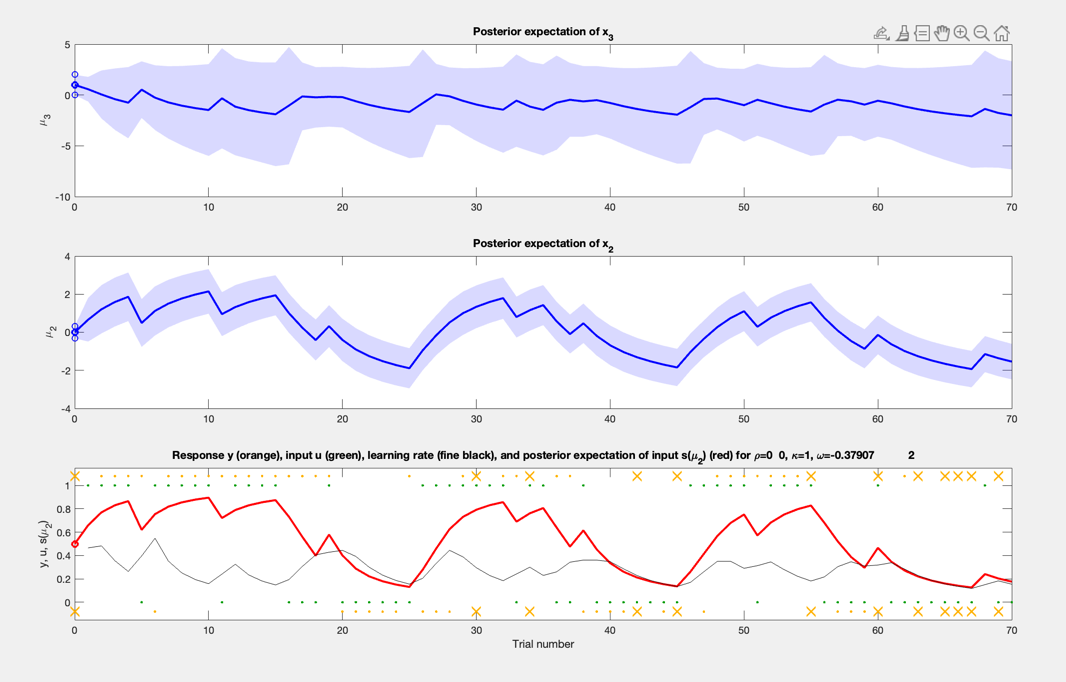

Generating such a plot of the model's estimated trajectories against your data is an essential sanity check before moving on to group-level analysis. In our case, this infant achieved a learning accuracy (correctly predicting which side the target would appear on) of 75.8% which is significantly above chance.

If we were to model the data of an infant with around chance accuracy (52%), we see some differences:

Parameter estimates for the perceptual model:
mu_0: [NaN 0 1]
sa_0: [NaN 0.1000 1]
rho: [NaN 0 0]
ka: [1 1]
om: [NaN -4.8824 2]
Parameter estimates for the observation model:

Invalid expression. Check for missing multiplication operator, missing or unbalanced delimiters, or other syntax error. To construct matrices, use brackets instead of parentheses.

be: 3.5637
Model quality:
LME (more is better): -40.774
AIC (less is better): 74.9811
BIC (less is better): 78.8448

First, we see that the value of ω2 is much lower (more negative). When we inspect the plotted trajectory, we see that the infant is not making precise predictions (red line on the bottom panel). Their learning rate is approximating 0, rather than adapting trialwise to the reinforcement schedule. This maps well onto the observational data (at-chance level accuracy).

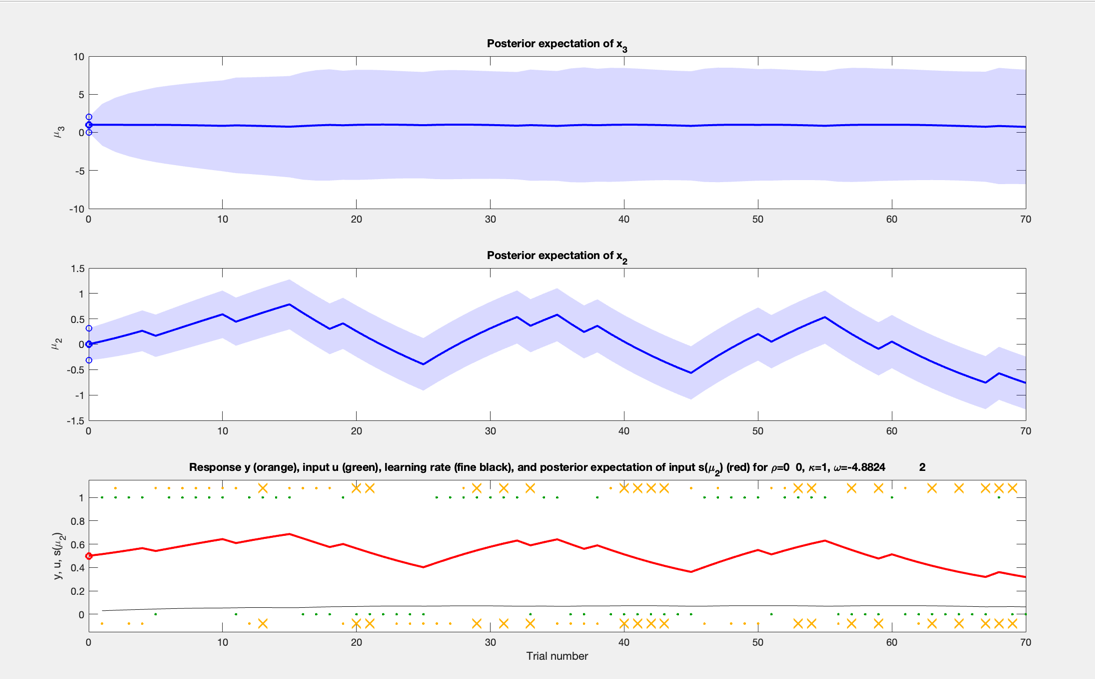

**5. Simulate data with your fitted parameters**

To know whether the model we chose actually describes the infant behaviour well, we need to perform some validation. We start by first simulating data: using the estimated parameters by the model for infant with subID 079 (ω2 = -0.38 and β=4.7), we simulate trialwise responses (anticipatory looks). If our model describes the data well, then the simulated data will be similar to the real data of that infant.

sim1 = tapas_simModel(u,...
                         'tapas_ehgf_binary',...
                         [est.p_prc.p],... % here, we take all estimated parameters
                         'tapas_softmax_binary',...
                         [est.p_obs.p]);

If we want to visualise the simulated responses, we can do so:

tapas_ehgf_binary_plotTraj(sim1)

We can see that the simulated response pattern closely resembles the original (aside from the missed trials). However, visual comparison alone isn't sufficient for formal validation: for that, we need to run these simulations multiple times and compare an aggregate summary (for example, the mean response per trial across all simulations) against the original pattern.

Here is one example how to do this. 

First, let's define how many simulations we want to run (we recommend at least 100; running more than that may slow down your machine).

n_sim = 100;  % number of simulations per subject\

Then we create a structure where we will save the simulations. We run the simulations in a loop, using the same set of models (perceptual tapas_ehgf_binary and response tapas_softmax_binary).

% Simulate n_sim datasets using the fitted model parameters
clear sim;

for c = 1:n_sim

    sim_temp = tapas_simModel(u, ...
        'tapas_ehgf_binary', ...
        [est.p_prc.p], ...
        'tapas_softmax_binary', ...
        [est.p_obs.p]);

    sim(c) = sim_temp;
end

% Aggregate simulated choices across simulations
sim_y = NaN(size(y, 1), n_sim);
for n = 1:n_sim
    sim_y(:, n) = sim(n).y;
end

% Build summary table: simulated vs. observed choices
num_rows = size(y, 1);

sim_y_mean_table = table( ...
    mode(sim_y, 2), ...            % most frequent simulated choice per trial
    mean(sim_y, 2), ...            % mean simulated choice per trial
    y(:, 1), ...                   % original observed choice
    (1:num_rows)', ...             % trial number
    u(:, 1), ...                   % target location
    'VariableNames', {'mode_sim_choice', 'mean_sim_choice', ...
    'og_choice', 'trial', 'target'});

When we visualise the simulated versus true responses, we see they match one another well:

figure;
plot(sim_y_mean_table.trial, sim_y_mean_table.og_choice, 'k-', 'LineWidth', 1.5); hold on;
plot(sim_y_mean_table.trial, sim_y_mean_table.mode_sim_choice, 'r--', 'LineWidth', 1.2);
xlabel('Trial');
ylabel('Choice (0 = Right, 1 = Left)');
legend('Observed Choice', 'Simulated Mode Choice', 'Location', 'best');
title('Observed vs. Simulated Choice Across Trials');
ylim([-0.2 1.2]);
box off;

We can perform formal validation in several ways: for example, by calculating the mean accuracy of the true and simulated data, and correlating them. The best way to do this is by performing the parameter estimation (step 4) and simulation (step 5) procedure for our entire sample, and then comparing group-level summary statistics, such as mean accuracy, win-stay rate, or lose-shift rate, between the true and simulated datasets across all participants, using a simple correlation to quantify how well the model reproduces these behavioral patterns at the population level.

**6. Parameter Recovery**

Behavioral validation tells us whether the model can reproduce an infant's observed choices but it doesn't tell us whether the model's estimated parameters are themselves trustworthy. A model could, in principle, generate realistic-looking behavior while still recovering unreliable or poorly identified parameter estimates. To check this, we perform **parameter recovery**: we simulate new data from known parameter values, refit the model to the simulated data, and then check how closely the recovered parameters match the original ones that generated the simulation. Strong parameter recovery gives us confidence that the parameter estimates from our real infant data are meaningful, rather than artifacts of the fitting procedure.

To do so, we will refit the same model to the simulated data.

rec_est = tapas_fitModel(sim_temp.y, ...
    u, ...
    my_perceptual_model_config, ...   % perceptual model
    'tapas_softmax_binary_config', ...   % response model
    'tapas_quasinewton_optim_config');

Here, we use the simulated responses (sim_temp`.y`) rather than the original responses (y).

We will then compare the parameter of interest (ω2) from the original fit and the newly recovered fit. The recovered ω2 is -1.18, which is somewhat lower than our original ω2 value of -0.38. However, as with simulations, we need to perform this multiple times, and get an average of this parameter to build a set of true vs. recovered parameter pairs. You should do this across your entire sample, in order to determine if your parameter of interest is recovered sufficiently well at the group level (i.e. if for the majority of infants, the recovered and true parameters correlate well).

## **What to do with the estimated parameters?**

Once your model validation procedures (behavioral validation and parameter recovery) suggest that the model captures your data well, you're ready to move on to substantive, hypothesis-driven analyses. This is where computational modelling really pays off: rather than working with raw behavioral data alone, you now have individual-level estimates such as tonic volatility (ω2) that represent meaningful, interpretable quantities about how each infant learns.

As with any analysis, your choice of question and ideally, your choice of computational model in the first place should be guided by your specific hypotheses. Below are some common ways researchers make use of estimated parameters like these.

**1. Relating parameters to individual differences**

One well-established approach in computational neuroscience and psychiatry is to test whether these parameters relate to individual differences in other domains: for example, temperament, caregiving environment, or clinical symptoms. Because the HGF gives you a parameter estimate per infant, these values can be entered directly into standard statistical models (e.g., regression, correlation) alongside questionnaire measures or other individual-difference variables, just as you would with any other continuous measure.

**2. Testing group-level differences**

Alternatively, you might be interested in whether these parameters differ systematically between groups or across development. For example, is tonic volatility (ω2) higher in older infants than younger ones, suggesting change reactivity increases with age? Or is it relatively stable across the age range you're studying, suggesting it behaves more like a trait-like individual difference than a developmental milestone? These questions can be addressed using standard group-comparison approaches (e.g., t-tests, ANOVAs, or mixed-effects models if you have repeated measures).

**3. Relating parameters to task performance or behavior**

You can also ask how these parameters relate to behavioral outcomes within your own task: for example, does higher ω2 predict better overall accuracy, or more optimal adaptation following a change in the environment? This can help validate that your parameters aren't just statistically estimable, but meaningfully connected to real behavioral differences.

**A note of caution**

Whichever analysis you choose, keep in mind that not all parameters are equally well-suited for individual-differences research. As discussed in the Parameter Recovery section above, some parameters (particularly higher-level ones like ω3) may be poorly identified with limited trial numbers, and should be interpreted with appropriate caution, or excluded from individual-differences analyses entirely if recovery is weak. As a rule of thumb, we recommend excluding any parameters who are not reasonable well recovered (correlation<0.5).